%2-A

im = imread('C:\Users\bengo\Downloads\test1.jpg')

im = 1831×1483×3 uint8 array
im(:,:,1) =

   210   209   208   208   209   210   211   211   208   209   210   209   208   208   210   211   210   210   211   210   209   208   209   211   211   211   210   210   209   209   208   208   212   211   211   210   210   210   210   211   212   211   211   211   211   211   210   209   210   211   211   211   210   210   211   211   211   212   212   213   213   214   214   214   215   212   210   208   209   210   210   209   209   210   211   210   208   208   210   212   209   209   208   208   208   208   209   209   210   210   210   210   210   210   210   210   210   210   210   210   211   211   212   212   211   213   212   210   210   213   214   213   211   212   212   212   212   212   213   213   210   211   211   212   212   213   213   213   212   211   210   210   210   211   211   211   211   211   211   210   210   211   212   213   214   211   209   210   210   210   209   210   210   211   211   212   212   212   212   2

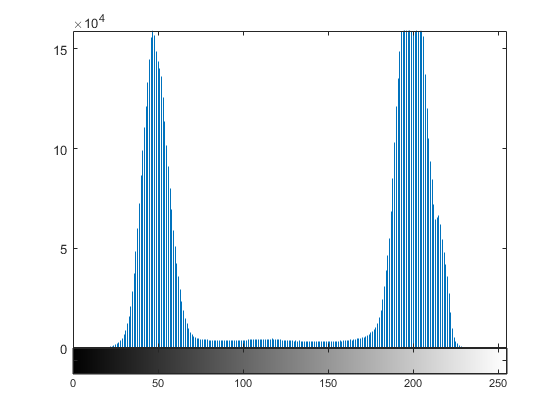

imhist(im)

filteredForeground = 1831×1483 uint8 matrix
   210   209   208   208   209   210   211   211   208   209   210   209   208   208   210   211   210   210   211   210   209   208   209   211   211   211   210   210   209   209   208   208   211   210   210   209   209   209   209   210   211   210   210   210   210   210   209   208   209   210
   209   209   208   209   209   210   210   209   209   210   210   209   208   208   209   210   209   210   210   210   209   209   210   211   210   210   210   209   209   208   208   208   210   209   209   208   208   208   208   209   210   210   209   209   210   210   210   209   210   211
   209   209   209   209   210   210   209   208   209   210   210   209   209   208   208   209   209   210   210   210   209   209   210   210   209   210   210   209   208   208   208   209   209   209   209   208   208   208   209   209   210   209   209   209   210   211   211   210   210   211
   209   208   208   209   209   210   209   209   20

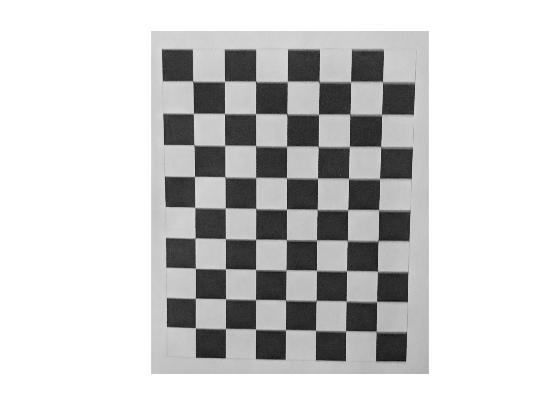

blobAnalysis =   vision.BlobAnalysis with properties:

                         AreaOutputPort: false
                     CentroidOutputPort: false
                  BoundingBoxOutputPort: true
              MajorAxisLengthOutputPort: false
              MinorAxisLengthOutputPort: false
                  OrientationOutputPort: false
                 EccentricityOutputPort: false
    EquivalentDiameterSquaredOutputPort: false
                       ExtentOutputPort: false
                    PerimeterOutputPort: false
                         OutputDataType: 'double'
                           Connectivity: 8
                  LabelMatrixOutputPort: false
                           MaximumCount: 50
                        MinimumBlobArea: 150
                        MaximumBlobArea: 4.2950e+09
                     ExcludeBorderBlobs: false


bbox = 6×4 int32 matrix
      1      1   1483   1831
    401   1272    162    166
    562   1114    323    329
    885   1118    165    167
   1045   1281    167    168
   1050    955    169    171


result = 1831×1483×3 uint8 array
result(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

numBlocks = 6

result = 1831×1483×3 uint8 array
result(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

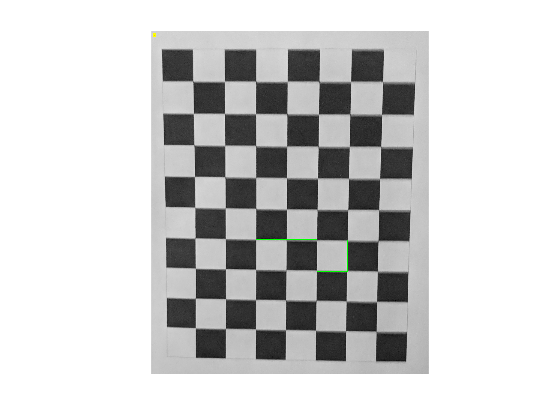


%2-B
%So, we don't need the video reader stuff since we're 
%reading in an image, not a video
se = strel('square', 3);
im1 = imcomplement(im)
im2 = imerode(im1,se)

filteredForeground = rgb2gray(imread('C:\Users\bengo\Downloads\test1.jpg'))
imshow(filteredForeground)

blobAnalysis = vision.BlobAnalysis('BoundingBoxOutputPort', true, ...
    'AreaOutputPort', false, 'CentroidOutputPort', false, ...
    'MinimumBlobArea', 150) %Based the minimum area to the 20x20 square area - 400 pixels
bbox = step(blobAnalysis, im2bw(im2))

result = insertShape(im2, 'Rectangle', bbox, 'Color', 'green')

numBlocks = size(bbox, 1)
result = insertText(result, [10 10], numBlocks, 'BoxOpacity', 1, ...
    'FontSize', 14)
%Not showing the detected regions for some odd reason
imshow(result)


%So, there are a few things I would like to conclude from this assignment
%1- The number of ID'd block is going to variable with images and image quality
%for some pictures I get 6 ID's blocks while for others I get much more
%2- In Part I of the MatLab documentation, it seems that training data
%is needed in order to proper identification to start; the results we 
%get for this particular experiment are highly unoptimized and are taken
%into regard with a large margin of error
%3- The only other way that I can think to do this is that there might be a probable use for image detection 
%in this case, but I just can't say for sure. I have a strong feeling 
%that he wants us to go that route, but I'm not sure how I want to plan/ 
%implement that within the preexisting bit of code.
